**1、读取数据**

% 读取导入数据
clc    
clear
fpath1 = "C:\Users\17630\Desktop\6.30\wines_SPA.csv";
T=readtable(fpath1);
head(T)

ans = 8×11 table
    index         winery                wine           year    rating    num_reviews           region                     type              body    acidity    price 
    _____    _________________    _________________    ____    ______    ___________    ____________________    ________________________    ____    _______    ______

      1      {'Teso La Monja'}    {'Tinto'        }    2013     4.9           58        {'Toro'            }    {'Toro Red'            }     5         3          995
      2      {'Artadi'       }    {'Vina El Pison'}    2018     4.9           31        {'Vino de Espana'  }    {'Tempranillo'         }     4         2        313.5
      3      {'Vega Sicilia' }    {'Unico'        }    2009     4.8         1793        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3       324.95
      4      {'Vega Sicilia' }    {'Unico'        }    1999     4.8         1705        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3

T1=T(:,2:end)

T1 = 7500×10 table
            winery                            wine                   year    rating    num_reviews           region                     type              body    acidity    price 
    _______________________    __________________________________    ____    ______    ___________    ____________________    ________________________    ____    _______    ______

    {'Teso La Monja'      }    {'Tinto'                         }    2013     4.9           58        {'Toro'            }    {'Toro Red'            }     5         3          995
    {'Artadi'             }    {'Vina El Pison'                 }    2018     4.9           31        {'Vino de Espana'  }    {'Tempranillo'         }     4         2        313.5
    {'Vega Sicilia'       }    {'Unico'                         }    2009     4.8         1793        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3       324.95
    {'Vega Sicilia'       }    {'Unico'                         }    1999     4.

disp('------------****分割线*****--------------')

------------****分割线*****--------------


**2、缺失值查看**

id = {'NA' '' -99 NaN Inf};
a1=sum(ismissing(T1,id));
a1'

ans =            0
           0
         290
           0
           0
           0
         545
        1169
        1169
         500


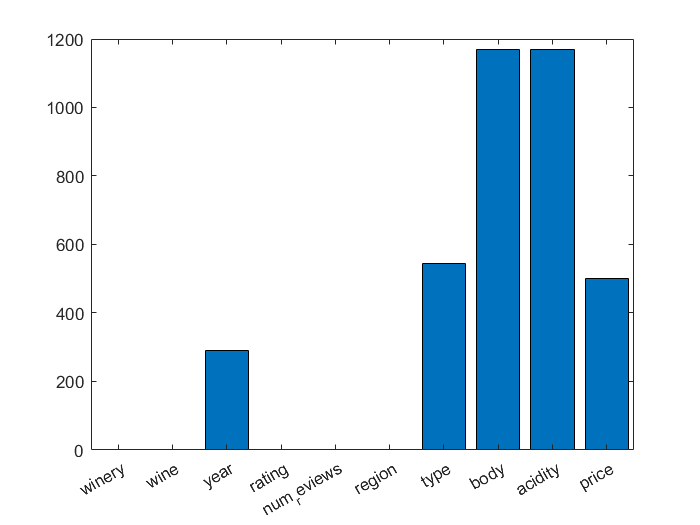

X = categorical(T1.Properties.VariableNames);
X = reordercats(X,T1.Properties.VariableNames);
Y = a1;
bar(X,Y)

disp(['缺失的总行数为：',num2str(sum(a1))])

缺失的总行数为：3673


disp('------------****分割线*****--------------')

------------****分割线*****--------------


**3、分组聚合查看**

%winery变量分组聚合
[nums,varnames]=groupcounts(T1.winery);
disp(['长度为',num2str(length(nums))])

长度为480


group_winery = table(varnames,nums)

group_winery = 480×2 table
                varnames                 nums
    _________________________________    ____

    {'A Coroa'                      }      1 
    {'AGE'                          }      1 
    {'Aalto'                        }     12 
    {'Abadal'                       }      3 
    {'Abadia Retuerta'              }     27 
    {'Abel Mendoza Monge'           }      4 
    {'Acustic Celler'               }      1 
    {'Adama Wines'                  }      4 
    {'Adega Familiar Eladio Pineiro'}      1 
    {'Agusti Torello Mata'          }      5 
    {'Albamar'                      }      1 
    {'Albet i Noya'                 }      2 
    {'Algueira'                     }      1 
    {'Alion'                        }     16 
    {'Allende'                      }     14 
    {'Alonso & Pedrajo'             }      1 



% %% 颜色定义
% map = addcolorplus(296);
% idx = linspace(1,64,10);
% idx = round(idx);
% C = map(idx,:);
% %%画图
% X = categorical(group_winery.varnames);
% X = reordercats(X,group_winery.varnames);
% GO = bar(X,group_winery.nums,0.6,'EdgeColor','k','LineWidth', 1);
% hXLabel = xlabel('winery');
% hYLabel = ylabel('nums');
% GO.FaceColor = 'flat';
% for i = 1:length(group_winery.nums)
%     GO.CData(i,:) = C(i,:);
% end

%wine变量分组聚合
[nums,varnames]=groupcounts(T1.wine);
disp(['长度为',num2str(size(nums))])

长度为847    1


group_wine = table(varnames,nums)

group_wine = 847×2 table
                               varnames                               nums
    ______________________________________________________________    ____

    {'1194'                                                      }     1  
    {'17'                                                        }     1  
    {'1730 Amontillado'                                          }     1  
    {'1730 Pedro Ximenez'                                        }     1  
    {'1902 Centenary Carignan Priorat'                           }     4  
    {'1903 Centenary Grenache'                                   }     1  
    {'200 Cestos Godello'                                        }     1  
    {'200 Monges Edicion Exclusiva Blanco Reserva'               }     1  
    {'200 Monges Rioja Gran Reserva'                             }     2  
    {'200 Monges Rioja Reserva'                                  }     5  
    {'200 Monges Rioja Reserva Seleccion Especial'               }     1  

%year变量分组聚合
[nums,varnames]=groupcounts(T1.year);
disp(['长度为',num2str(size(nums))])

长度为71   1


group_year = table(varnames,nums)

group_year = 71×2 table
    varnames    nums
    ________    ____

      1910       1  
      1922       1  
      1925       1  
      1928       1  
      1929       1  
      1931       1  
      1942       1  
      1946       2  
      1949       1  
      1951       1  
      1953       1  
      1954       1  
      1955       2  
      1958       1  
      1959       2  
      1961       1  


%rating变量分组聚合
[nums,varnames]=groupcounts(T1.rating);
disp(['长度为',num2str(length(nums))])

长度为8


group_rating = table(varnames,nums)

group_rating = 8×2 table
    varnames    nums
    ________    ____

      4.2       5679
      4.3        707
      4.4        484
      4.5        281
      4.6        191
      4.7        112
      4.8         44
      4.9          2


%region变量分组聚合
[nums,varnames]=groupcounts(T1.region);
disp(['长度为',num2str(length(nums))])

长度为76


group_region = table(varnames,nums)

group_region = 76×2 table
           varnames            nums
    _______________________    ____

    {'Abona'              }      1 
    {'Alella'             }      4 
    {'Alicante'           }    233 
    {'Almansa'            }      7 
    {'Andalucia'          }      4 
    {'Aragon'             }      2 
    {'Arinzano'           }      3 
    {'Arribes'            }      1 
    {'Bierzo'             }    244 
    {'Binissalem-Mallorca'}      1 
    {'Cadiz'              }      7 
    {'Calatayud'          }      2 
    {'Campo de Borja'     }     16 
    {'Carinena'           }      3 
    {'Castilla'           }      8 
    {'Castilla y Leon'    }     51 


% type变量分组聚合
[nums,varnames]=groupcounts(T1.type);
disp(['长度为',num2str(length(nums))])

长度为22


group_type = table(varnames,nums)

group_type = 22×2 table
            varnames            nums
    ________________________    ____

    {'Albarino'            }     252
    {'Cabernet Sauvignon'  }      11
    {'Cava'                }      33
    {'Chardonnay'          }      13
    {'Grenache'            }      35
    {'Mencia'              }     235
    {'Monastrell'          }      18
    {'Montsant Red'        }      17
    {'NA'                  }     545
    {'Pedro Ximenez'       }      35
    {'Priorat Red'         }     674
    {'Red'                 }     864
    {'Ribera Del Duero Red'}    1407
    {'Rioja Red'           }    2357
    {'Rioja White'         }      92
    {'Sauvignon Blanc'     }       4


%body变量分组聚合
[nums,varnames]=groupcounts(T1.body);
disp(['长度为',num2str(length(nums))])

长度为5


group_body = table(varnames,nums)

group_body = 5×2 table
    varnames    nums
    ________    ____

        2         34
        3        553
        4       4120
        5       1624
      NaN       1169


% acidity变量分组聚合
[nums,varnames]=groupcounts(T1.acidity);
disp(['长度为',num2str(length(nums))])

长度为4


group_acidity = table(varnames,nums)

group_acidity = 4×2 table
    varnames    nums
    ________    ____

        1         35
        2        268
        3       6028
      NaN       1169



% num_reviews变量分组聚合
[nums,varnames]=groupcounts(T1.acidity);
disp(['长度为',num2str(length(nums))])

长度为4


group_acidity = table(varnames,nums)

group_acidity = 4×2 table
    varnames    nums
    ________    ____

        1         35
        2        268
        3       6028
      NaN       1169


**4、描述分析**

summary(T1)

Variables:

    winery: 7500×1 cell array of character vectors

    wine: 7500×1 cell array of character vectors

    year: 7500×1 double

        Values:

            Min             1910  
            Median          2015  
            Max             2021  
            NumMissing      290   

    rating: 7500×1 double

        Values:

            Min         4.2   
            Median      4.2   
            Max         4.9   

    num_reviews: 7500×1 double

        Values:

            Min           25  
            Median       404  
            Max        32624  

    region: 7500×1 cell array of character vectors

    type: 7500×1 cell array of character vectors

    body: 7500×1 double

        Values:

            Min             2     
            Median          4     
            Max             5     
            NumMissing      1169  

 

**5、缺失值填充**

%%body缺失问题使用固定值1来填充
constant_body=1;
T1{:,"body"}=fillmissing(T1{:,"body"},"constant",constant_body)

T1 = 7500×10 table
            winery                            wine                   year    rating    num_reviews           region                     type              body    acidity    price 
    _______________________    __________________________________    ____    ______    ___________    ____________________    ________________________    ____    _______    ______

    {'Teso La Monja'      }    {'Tinto'                         }    2013     4.9           58        {'Toro'            }    {'Toro Red'            }     5         3          995
    {'Artadi'             }    {'Vina El Pison'                 }    2018     4.9           31        {'Vino de Espana'  }    {'Tempranillo'         }     4         2        313.5
    {'Vega Sicilia'       }    {'Unico'                         }    2009     4.8         1793        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3       324.95
    {'Vega Sicilia'       }    {'Unico'                         }    1999     4.

%%对于year缺失问题，使用固定值填充3000
constant_year=3000;
T1{:,"year"}=fillmissing(T1{:,"year"},"constant",constant_year)

T1 = 7500×10 table
            winery                            wine                   year    rating    num_reviews           region                     type              body    acidity    price 
    _______________________    __________________________________    ____    ______    ___________    ____________________    ________________________    ____    _______    ______

    {'Teso La Monja'      }    {'Tinto'                         }    2013     4.9           58        {'Toro'            }    {'Toro Red'            }     5         3          995
    {'Artadi'             }    {'Vina El Pison'                 }    2018     4.9           31        {'Vino de Espana'  }    {'Tempranillo'         }     4         2        313.5
    {'Vega Sicilia'       }    {'Unico'                         }    2009     4.8         1793        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3       324.95
    {'Vega Sicilia'       }    {'Unico'                         }    1999     4.


%对于type使用临近值填充
T1{:,"type"}=fillmissing(T1{:,"type"},"nearest")

T1 = 7500×10 table
            winery                            wine                   year    rating    num_reviews           region                     type              body    acidity    price 
    _______________________    __________________________________    ____    ______    ___________    ____________________    ________________________    ____    _______    ______

    {'Teso La Monja'      }    {'Tinto'                         }    2013     4.9           58        {'Toro'            }    {'Toro Red'            }     5         3          995
    {'Artadi'             }    {'Vina El Pison'                 }    2018     4.9           31        {'Vino de Espana'  }    {'Tempranillo'         }     4         2        313.5
    {'Vega Sicilia'       }    {'Unico'                         }    2009     4.8         1793        {'Ribera del Duero'}    {'Ribera Del Duero Red'}     5         3       324.95
    {'Vega Sicilia'       }    {'Unico'                         }    1999     4.

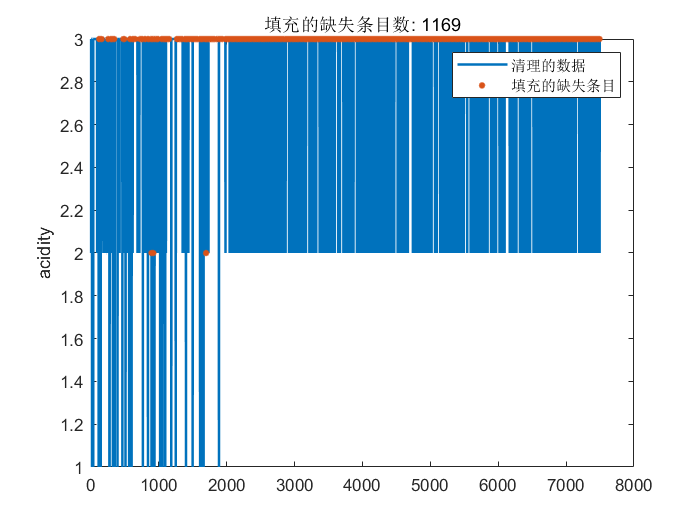

% 填充缺失数据
[T1,missingIndices] = fillmissing(T1,"nearest","DataVariables","acidity");

% 显示结果
clf
plot(T1.acidity,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","清理的数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices(:,9)),T1.acidity(missingIndices(:,9)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices(:,9)))

hold off
legend
ylabel("acidity")

clear missingIndices

sum(ismissing(T1))

ans =      0     0     0     0     0     0     0     0     0   500


**5、词云图**

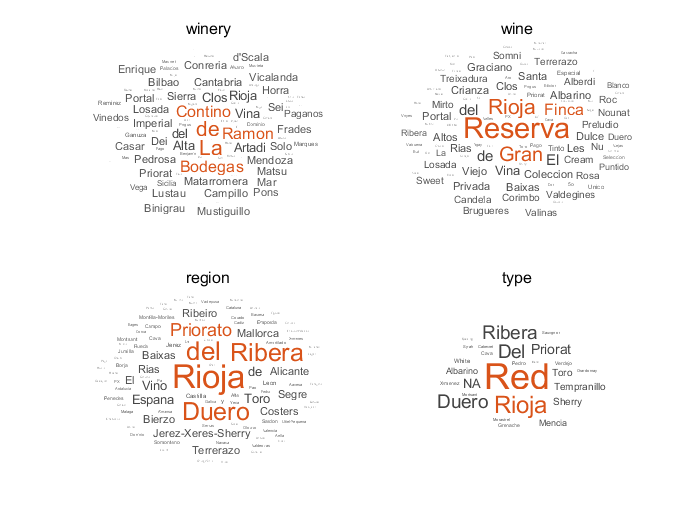

subplot(2,2,1)
wordcloud(T1.winery);
title('winery');
subplot(2,2,2)
wordcloud(T1.wine);
title('wine');
subplot(2,2,3)
wordcloud(T1.region);
title('region');
subplot(2,2,4)
wordcloud(T1.type);
title('type');

**6、简单回归尝试**

%选取acidity,body,rating,price构建一个表格,进行简单相关性分析和回归分析
T2=T1(1:7000,{'acidity','body','rating','price'})

T2 = 7000×4 table
    acidity    body    rating    price 
    _______    ____    ______    ______

       3        5       4.9         995
       2        4       4.9       313.5
       3        5       4.8      324.95
       3        5       4.8      692.96
       3        5       4.8      778.06
       3        5       4.8         490
       3        5       4.8         349
       3        5       4.8      810.89
       3        5       4.8         345
       3        5       4.8         315
       3        5       4.8      514.85
       3        5       4.8      105.15
       3        5       4.8         430
       3        5       4.8         925
       1        5       4.8         350
       3        5       4.8      166.18


data=zscore(T2{:,:})

data =          0.198151285750299          1.05043670719375          5.28894252177743          6.00452633446243
         -4.10948536099536         0.264265751312615          5.28894252177743          1.61762046587712
         0.198151285750299          1.05043670719375           4.4640183316608          1.69132563417544
         0.198151285750299          1.05043670719375           4.4640183316608           4.0602548032115
         0.198151285750299          1.05043670719375           4.4640183316608          4.60805478768195
         0.198151285750299          1.05043670719375           4.4640183316608           2.7537743702136
         0.198151285750299          1.05043670719375           4.4640183316608          1.84613867326491
         0.198151285750299          1.05043670719375           4.4640183316608          4.81938585102113
         0.198151285750299          1.05043670719375           4.4640183316608          1.82039014285502
         0.198151285750299          1.0504367071

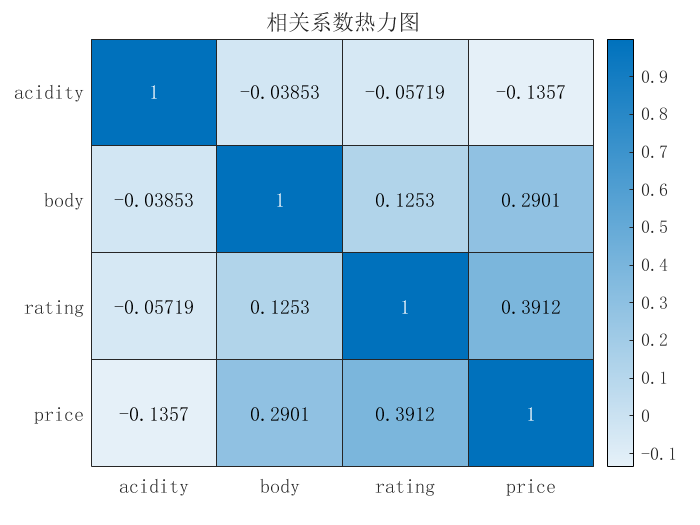

xvalues = {'acidity','body','rating','price'};
yvalues ={'acidity','body','rating','price'};
%  Kendall tau 系数
figure
[corr_data,~]=corr(data,'Type','Kendall');
H = heatmap(xvalues,yvalues,corr_data, 'FontSize',12, 'FontName','宋体');
H.Title = '相关系数热力图';

**7、数值转化填充**

T1.winery=double(categorical(T1.winery));
T1.wine=double(categorical(T1.wine));
T1.year=double(categorical(T1.year));
T1.type=double(categorical(T1.type));
T1.region=double(categorical(T1.region));
train_data=T1(1:7000,:)

train_data = 7000×10 table
    winery    wine    year    rating    num_reviews    region    type    body    acidity    price 
    ______    ____    ____    ______    ___________    ______    ____    ____    _______    ______

     423      760      62      4.9           58          70       21      5         3          995
      34      820      67      4.9           31          75       20      4         2        313.5
     448      779      58      4.8         1793          58       13      5         3       324.95
     448      779      48      4.8         1705          58       13      5         3       692.96
     448      779      45      4.8         1309          58       13      5         3       778.06
     448      779      47      4.8         1209          58       13      5         3          490
     448      779      59      4.8         1201          58       13      5         3          349
     448      779      44      4.8          926          58       13      5      

submit_test=T1(7001:end,:)

submit_test = 500×10 table
    winery    wine    year    rating    num_reviews    region    type    body    acidity    price
    ______    ____    ____    ______    ___________    ______    ____    ____    _______    _____

     391      663      66      4.2          421          60       15      3         3        NaN 
     272      620      64      4.2          420          60       14      4         3        NaN 
     201      691      66      4.2          420           3       12      4         3        NaN 
     153      676      60      4.2          420          22       12      4         3        NaN 
     410      184      61      4.2          420          60       14      4         3        NaN 
     251      670      53      4.2          417          60       14      4         3        NaN 
     286       57      67      4.2          415           9        6      3         3        NaN 
     293      640      64      4.2          414          55        1      3         3     

**8、聚类操作**

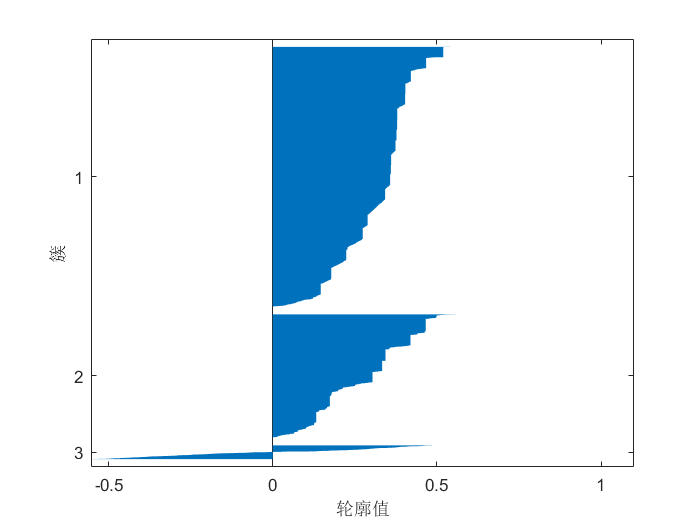

zs_data=zscore(train_data{:,:});
[cidx2,cmeans2] = kmeans(zs_data,3,'dist','sqeuclidean');
% 计算轮廓系数并作图
[silh2,h] = silhouette(zs_data,cidx2,'sqeuclidean');

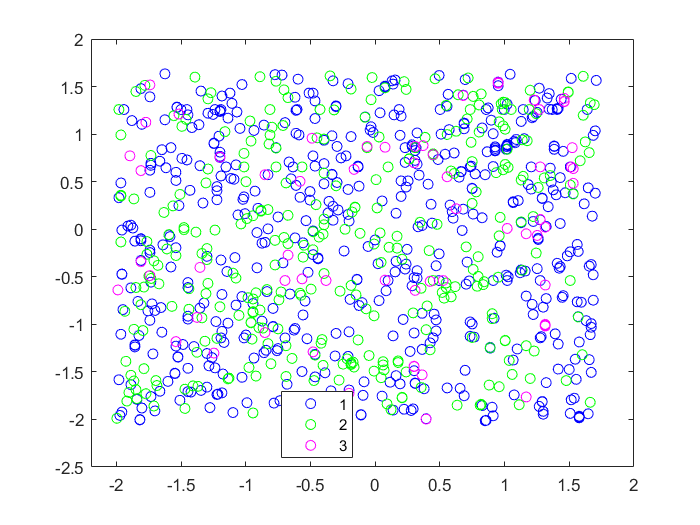

% 利用meas中前两列画出聚类结果的二维图
gscatter(zs_data(:,1),zs_data(:,2),cidx2,'bgm','ooo')

**9、机器学习模型**